## Cross-zone analysis

Doing an util file to deep dive into the data of the zones so we can have a much bigger picture

clear;
dataFolder = "data";
zoneIds = [8, 9, 10, 11];
zoneNames = ["Anagnina", "Trieste", "Della Vittoria", "Tor di Quinto"];

zoneDataList = cell(numel(zoneIds), 1);
for i = 1:numel(zoneIds)
    zoneDataList{i} = loadZoneData(dataFolder, zoneIds(i));
end

Data for zone "Zone_1016_Anagnina" loaded correctly (2784 rows x 17 columns).
Data for zone "Zone_214_Trieste" loaded correctly (2784 rows x 17 columns).
Data for zone "Zone_2004_Della Vittoria,Tomba di Nerone,Tor di Quinto2" loaded correctly (2784 rows x 17 columns).
Data for zone "Zone2002_Tor di Quinto6" loaded correctly (2784 rows x 17 columns).


timeVector = zoneDataList{1}.datetime;
energyMatrix = [zoneDataList{1}.AAC_energy, zoneDataList{2}.AAC_energy, ...
    zoneDataList{3}.AAC_energy, zoneDataList{4}.AAC_energy];

## Temporal synchrony

We evaluate temporal correlation across zones by plotting the Pearson correlation matrix of AAC_energy as a heatmap.

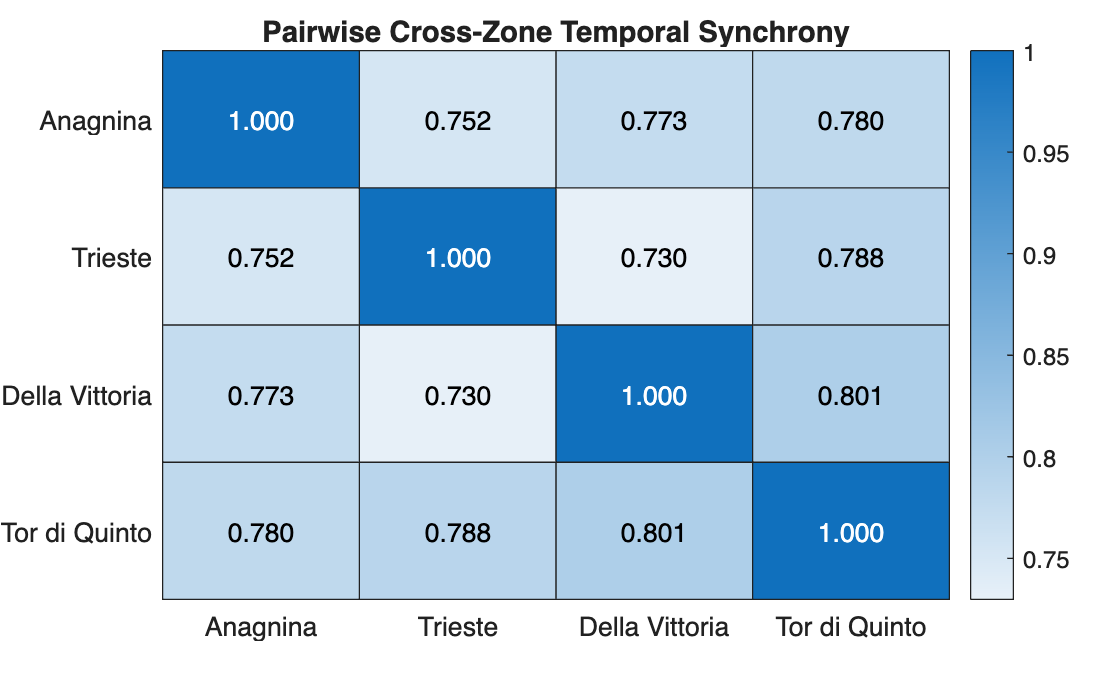

temporalCorr = corrcoef(energyMatrix);

figure
heatmap(zoneNames, zoneNames, temporalCorr, CellLabelFormat="%.3f")
title("Pairwise Cross-Zone Temporal Synchrony")

Pairwise correlation coefficients range from 0.73 to 0.80 across the four zones, showing strong temporal coherence among the oscillations.  

## Weekday vs Weekend/Holiday

Identifying non-working days: weekends or official calendar holidays

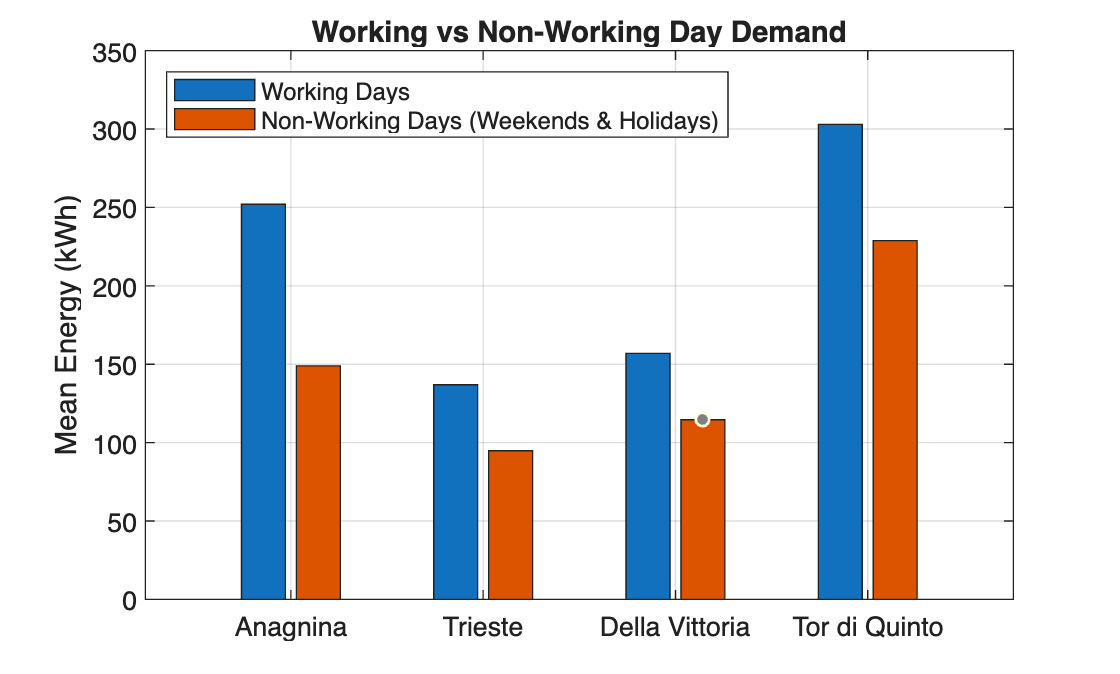

isNonWorking = isweekend(timeVector) | (zoneDataList{1}.holiday_proximity > 0.99);
workingMeans = mean(energyMatrix(~isNonWorking, :));
nonWorkingMeans = mean(energyMatrix(isNonWorking, :));
figure
bar(categorical(zoneNames, zoneNames), [workingMeans', nonWorkingMeans'])
title("Working vs Non-Working Day Demand")
ylabel("Mean Energy (kWh)")
legend(["Working Days", "Non-Working Days (Weekends & Holidays)"], Location="northwest")
grid on

Across all four districts, consumption falls on non-working days. Anagnina drops by 40.9 (from 252.0 to 148.9 kWh), reflecting its commuter traffic toward the metro and highway. Trieste drops by 30.7 (136.9 to 94.8 kWh), Della Vittoria by 27.0 (156.9 to 114.6 kWh), and Tor di Quinto by 24.5 (303.0 to 228.9 kWh), showing steadier demand as a main transit corridor.

## Shape alignment based on mean AAC_energy

Mapping timestamps to 48 half-hour bins (1 = 00:00, 2 = 00:30, ..., 48 = 23:30) and using two loops, calculating the mean consumption per time slot across the dataset to build the 48x4 dailyProfiles matrix. Then computing shapeCorr, the correlation matrix across the four daily curves. To see results, displaying a two-panel tiled layout: the left plot shows the four 24-hour profiles (x: 0:0.5:23.5), while the right heatmap displays pairwise shape correlations. This isolates the circadian pattern from day-to-day noise, so zones with weak instantaneous correlation due to local timing differences can still show strong shape alignment if their overall daily habits match.

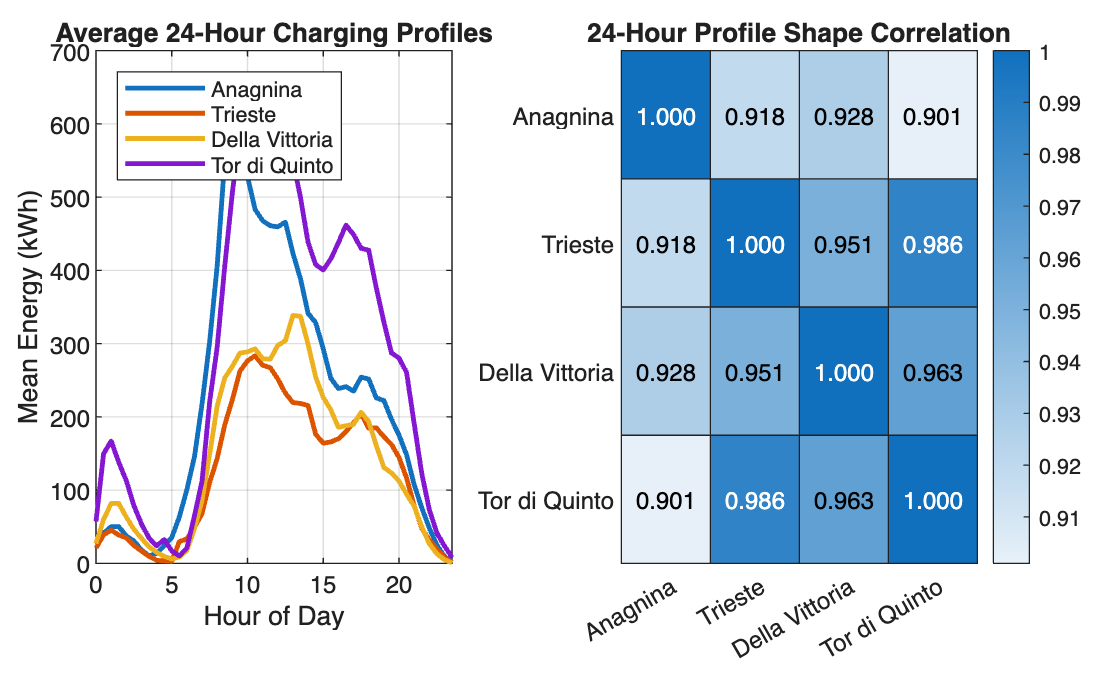

dailyProfiles = zeros(48, numel(zoneIds));
halfHourIndex = hour(timeVector) * 2 + minute(timeVector)/30 + 1;

for i = 1:numel(zoneIds)
    for h = 1:48
        dailyProfiles(h, i) = mean(energyMatrix(halfHourIndex == h, i));
    end
end

shapeCorr = corrcoef(dailyProfiles);

figure
tiledlayout(1, 2, Padding="compact", TileSpacing="compact")

nexttile
plot(0:0.5:23.5, dailyProfiles, LineWidth=1.8)
title("Average 24-Hour Charging Profiles")
xlabel("Hour of Day")
ylabel("Mean Energy (kWh)")
legend(zoneNames, Location="northwest")
grid on

nexttile
heatmap(zoneNames, zoneNames, shapeCorr, CellLabelFormat="%.3f")
title("24-Hour Profile Shape Correlation")

With correlation coefficients exceeding 0.9 across all zones, the curves and oscillations follow very similar patterns.

## Range and Zeros for AAC_energy

We flatten energyMatrix into a single vector and repeat zone labels with repelem for categorical grouping. We compute idlePct by dividing zero-consumption counts (sum(energyMatrix == 0)) by total rows to find the inactive share.

To see results, we plot two charts side by side: a boxchart showing medians, quartiles, and outliers on the left, and a bar chart of idle percentages on the right. This highlights structural differences across zones, such as residential idle stretches versus steady commercial load. While daily curves share 95% shape similarity, zones differ in baseline and amplitude:

y_i(t) = mu_i + sigma_i * z(t). 

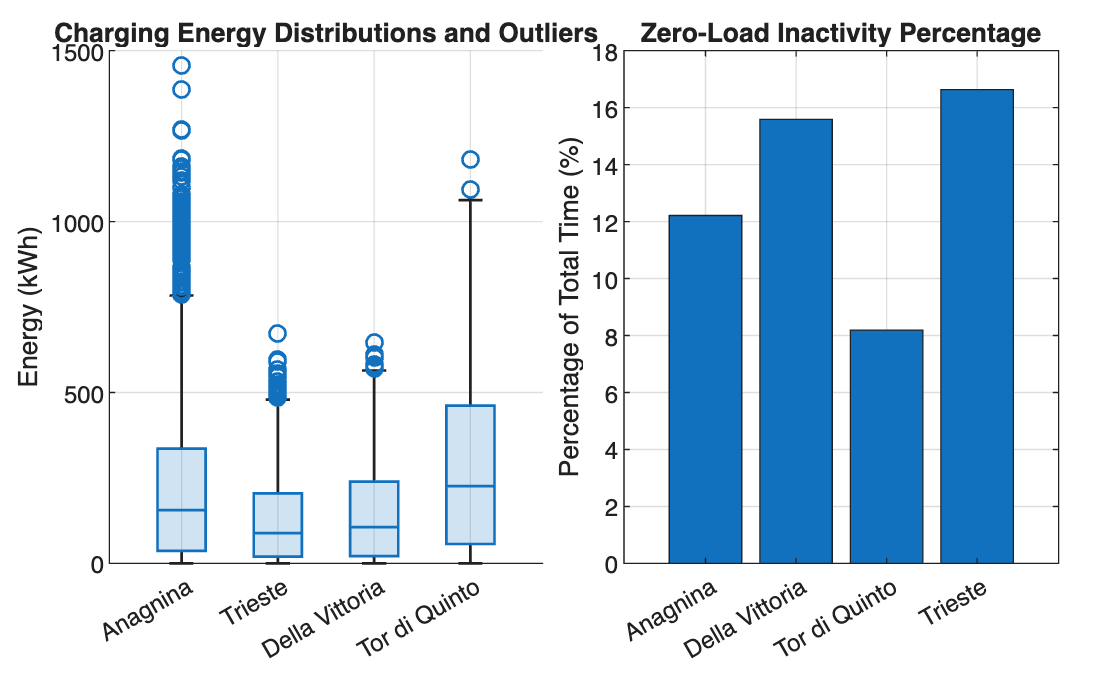

stackedEnergy = energyMatrix(:);
stackedLabels = repelem(zoneNames, height(energyMatrix));

idlePct = sum(energyMatrix == 0) ./ height(energyMatrix) * 100;

figure
tiledlayout(1, 2, Padding="compact", TileSpacing="compact")

nexttile
boxchart(categorical(stackedLabels, zoneNames), stackedEnergy)
title("Charging Energy Distributions and Outliers")
ylabel("Energy (kWh)")
grid on

nexttile
bar(categorical(zoneNames), idlePct)
title("Zero-Load Inactivity Percentage")
ylabel("Percentage of Total Time (%)")
grid on

For example, Tor di Quinto (mean 281.8 kWh, std 249.4 kWh, 8.2% idle) uses roughly 2.26 times more energy than Trieste (mean 124.9 kWh, std 121.8 kWh, 16.6% idle), but normalizing by mean and standard deviation isolates the shared dynamic z(t).

## Temperature slope

We extract temperature data from the first zone since weather is uniform across the city, then create a 2x2 grid layout. 

For each zone, we plot a semi-transparent scatter plot (MarkerFaceAlpha = 0.25) of temperature against charging consumption, fit a linear regression with polyfit and polyval, overlay the red trendline, and display the slope in the title. This quantifies thermal sensitivity: consumption increases with temperature across all zones, and slopes scale proportionally with overall district demand:

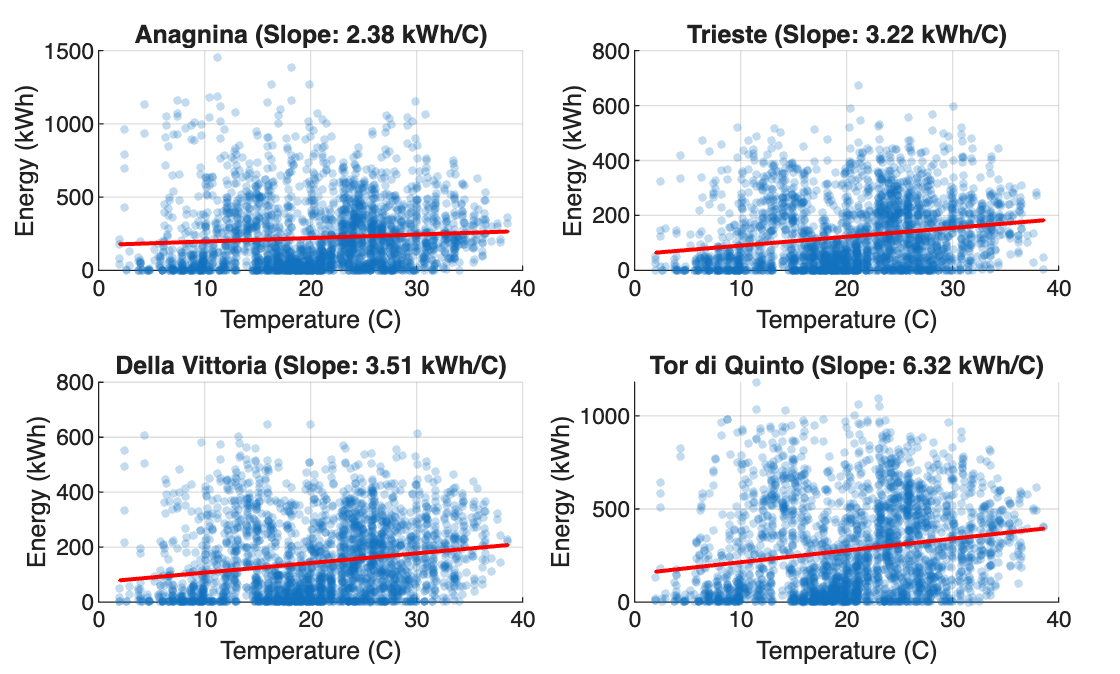

temperature = zoneDataList{1}.temp;

figure
tiledlayout(2, 2, Padding="compact", TileSpacing="compact")

for i = 1:numel(zoneIds)
    nexttile
    scatter(temperature, energyMatrix(:, i), 10, "filled", MarkerFaceAlpha=0.25)
    hold on

    coeff = polyfit(temperature, energyMatrix(:, i), 1);
    fittedLine = polyval(coeff, temperature);
    plot(temperature, fittedLine, "r-", LineWidth=1.5)
    hold off

    title(sprintf("%s (Slope: %.2f kWh/C)", zoneNames(i), coeff(1)))
    xlabel("Temperature (C)")
    ylabel("Energy (kWh)")
    grid on
end

We calculate temperature sensitivity slopes across all zones: Anagnina (+2.38 kWh/°C), Trieste (+3.22 kWh/°C), Della Vittoria (+3.51 kWh/°C) and Tor di Quinto (+6.32 kWh/°C). 

Consumption increases with temperature in every zone, with sensitivity scaling directly with each district's overall energy volume.